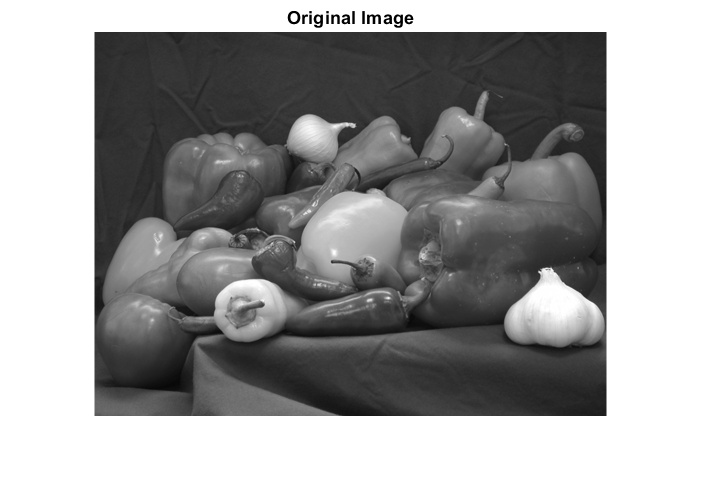

img = im2double(rgb2gray(imread('peppers.png')));
imshow(img);
title('Original Image')

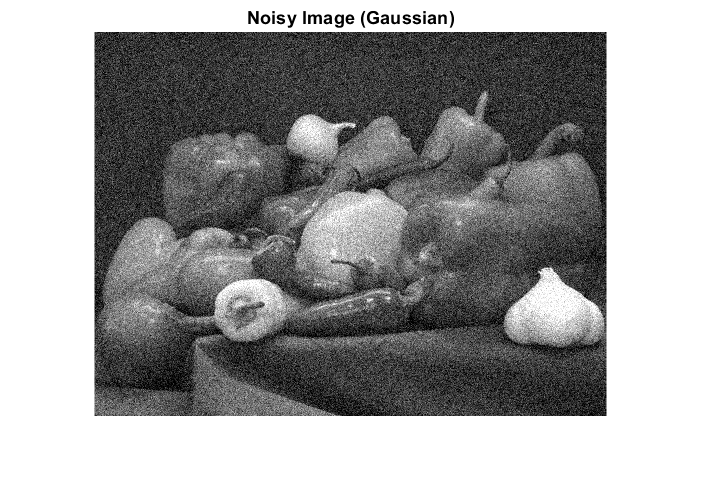


imgn1 = imnoise(img, 'gaussian',0.01);
imshow(imgn1)
title('Noisy Image (Gaussian)')

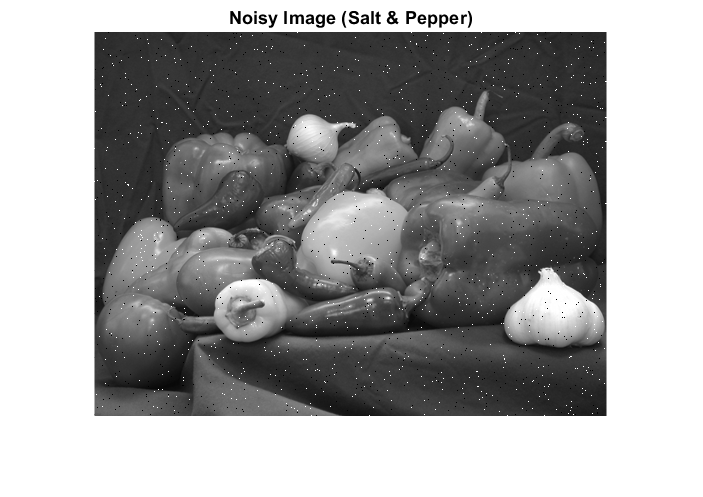


imgn2 = imnoise(img,'salt & pepper',0.01);
imshow(imgn2)
title('Noisy Image (Salt & Pepper)')

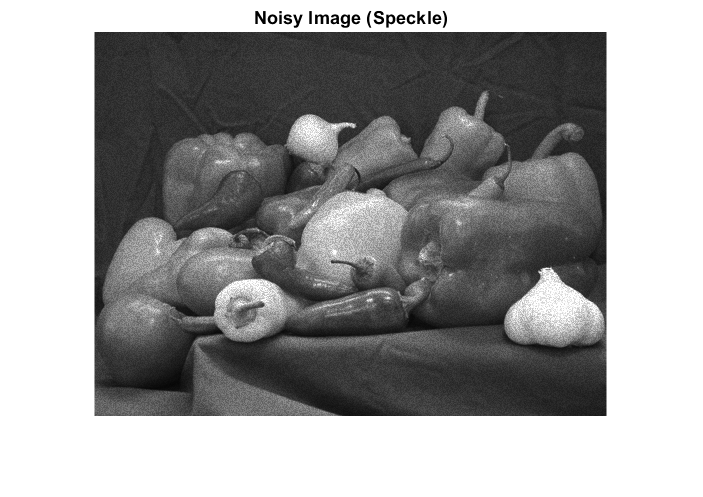


imgn3 = imnoise(img, 'speckle',0.01);
imshow(imgn3)
title('Noisy Image (Speckle)')

## PRINCIPLE COMPONENT ANALYSIS

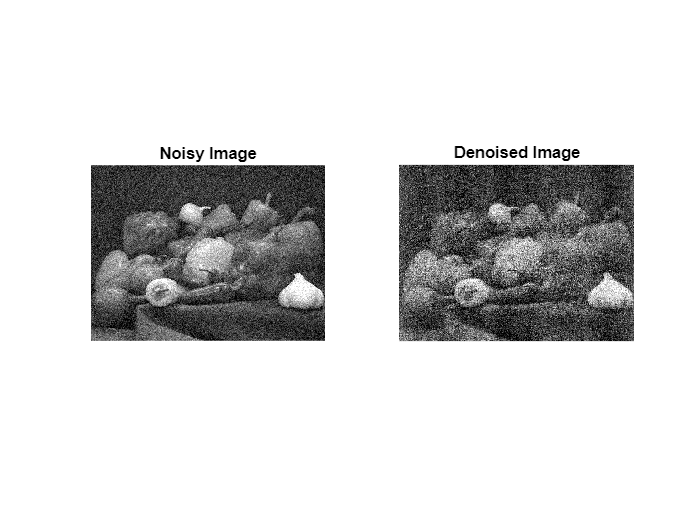

% Load the image
img = imread('peppers.png');

% Convert the image to grayscale
img = rgb2gray(img);

% Add noise to the image
noisy_img = imnoise(img,'gaussian',0,0.05);

% Perform PCA on the noisy image
[coeff,score,latent] = pca(double(noisy_img));

% Keep only the top k principal components
k = 100;
coeff = coeff(:,1:k);

% Reconstruct the image using the top k principal components
reconstructed_img = uint8(score(:,1:k) * coeff' + mean(noisy_img(:)));

figure;
subplot(1,2,1);
imshow(imgn1);
title('Noisy Image');
subplot(1,2,2);
imshow(reconstructed_img);
title('Denoised Image');

psnr(noisy_img,reconstructed_img)

ans = 17.2563

## SINGULAR VALUE DECOMPOSITION

Performs SVD on the image, sets a threshold for the singular values, replaces all singular values below the threshold with zero, and then uses the modified S matrix to reconstruct the image. 

NEED TO FIND APPROPRIATE THRESHOLD VALUE

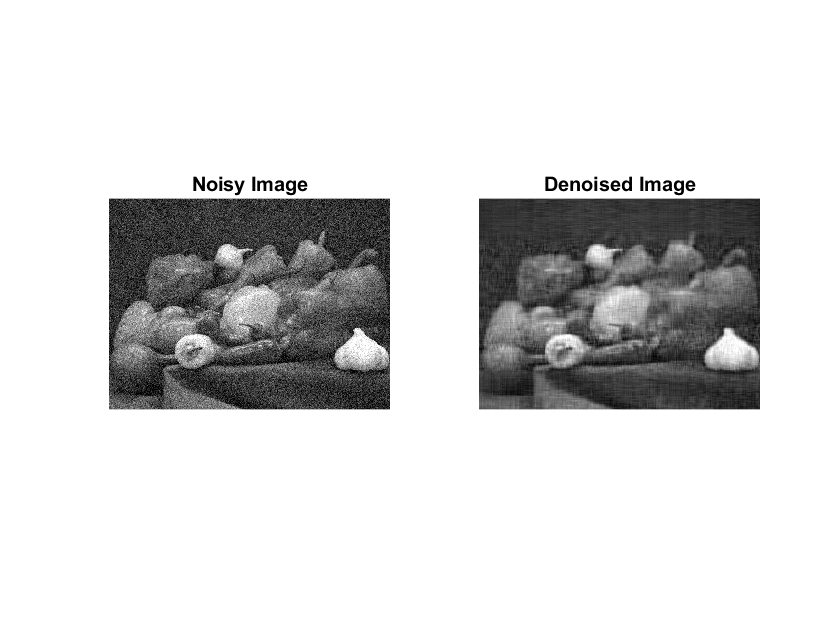

% Perform SVD on the image
[U,S,V] = svd(double(imgn1));
% Set a threshold for the singular values
threshold = 5;
% Replace all singular values below the threshold with zero
S(S < threshold) = 0;
% Reconstruct the image using the modified S matrix
img_denoised = U*S*V';
% Convert the image back to uint8 and display
%img_denoised = uint8(img_denoised);

figure;
subplot(1,2,1);
imshow(imgn1);
title('Noisy Image');
subplot(1,2,2);
imshow(img_denoised);
title('Denoised Image');

## DISCRETE COSINE TRANSFORM

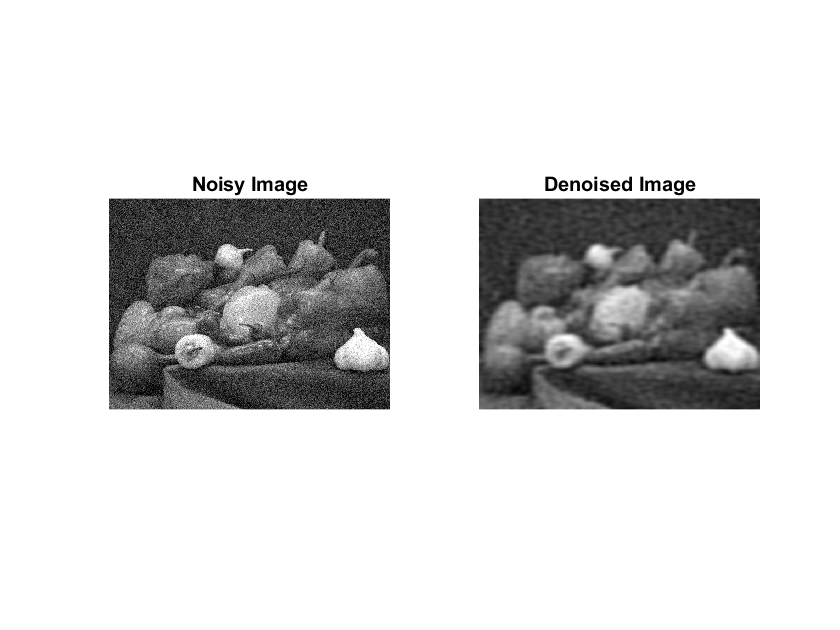

dct_img = dct2(imgn1);

% Set a threshold value for DCT coefficients
threshold = 0.5;
% Set DCT coefficients below the threshold to zero
dct_img(abs(dct_img) < threshold) = 0;
% Apply the inverse DCT to the thresholded image
denoised_img = idct2(dct_img);
figure;
subplot(1,2,1);
imshow(imgn1);
title('Noisy Image');
subplot(1,2,2);
imshow(denoised_img);
title('Denoised Image');

## WAVELET

(Mams code)

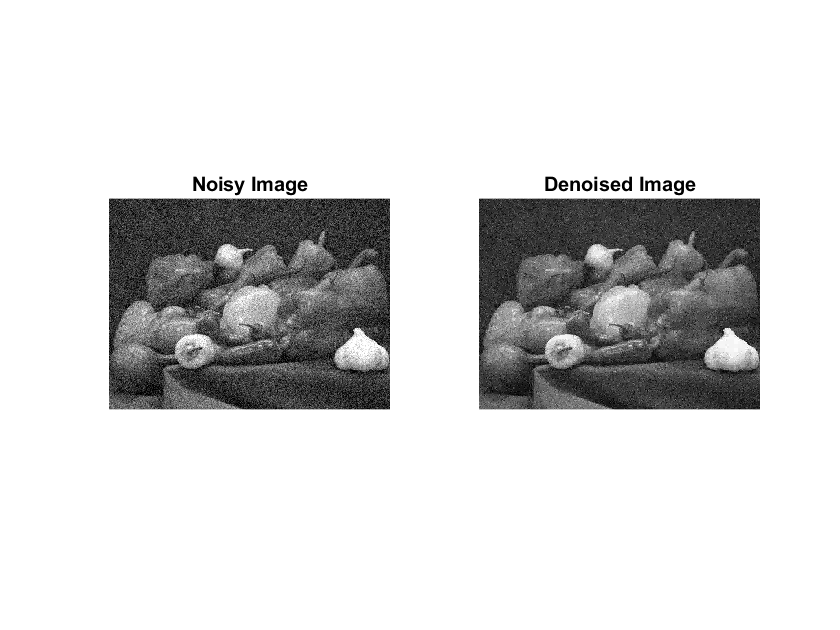

x1 = imgn1;
sigma=0.08;
[c l]=wavedec2(x1,4,'haar');
T=2*sigma;
a=appcoef2(c,l,'haar',1);
[h v d]=detcoef2('all',c,l,1);
l1=[a h; v d];
a=appcoef2(c,l,'haar',2);
[h2 v2 d2]=detcoef2('all',c,l,2);
l2=[a h2; v2 d2];
l2_f=[l2 h; v d];
c1=c.*(abs(c)>T);
x_denoise=waverec2(c1,l,'haar');
figure;
subplot(1,2,1);imshow(x1); title('Noisy Image');
subplot(1,2,2);imshow(x_denoise); title('Denoised Image');

Other code

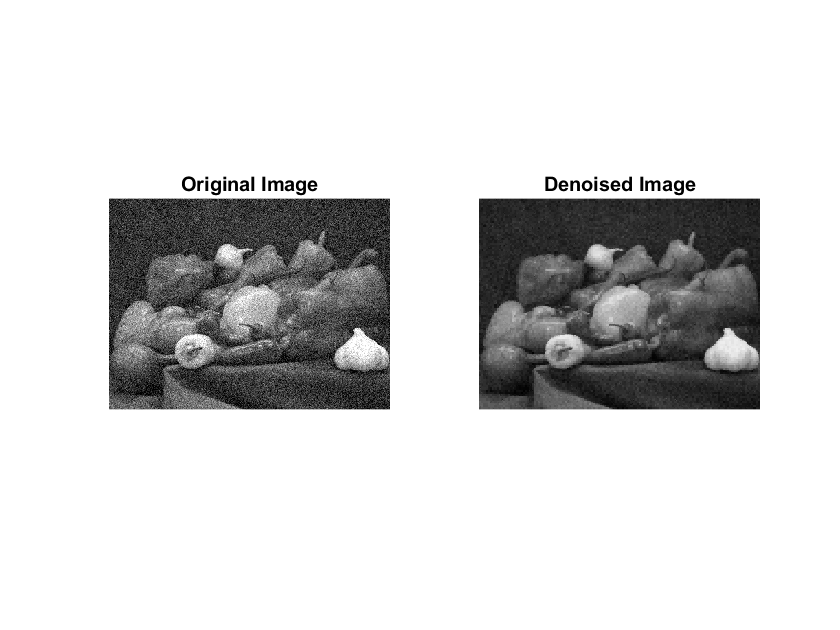

% Load the image
img = imgn1;
% Perform the wavelet transform
[c,s] = wavedec2(img,2,'db1');
% Define the threshold value for denoising
threshold = 0.2;
% Apply the threshold to the coefficients
c = wthresh(c,'s',threshold);
% Perform the inverse wavelet transform
img_denoised = waverec2(c,s,'db1');
% Display the original and denoised images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_denoised);
title('Denoised Image');

## Non-negative Matrix Factorization (NMF) 

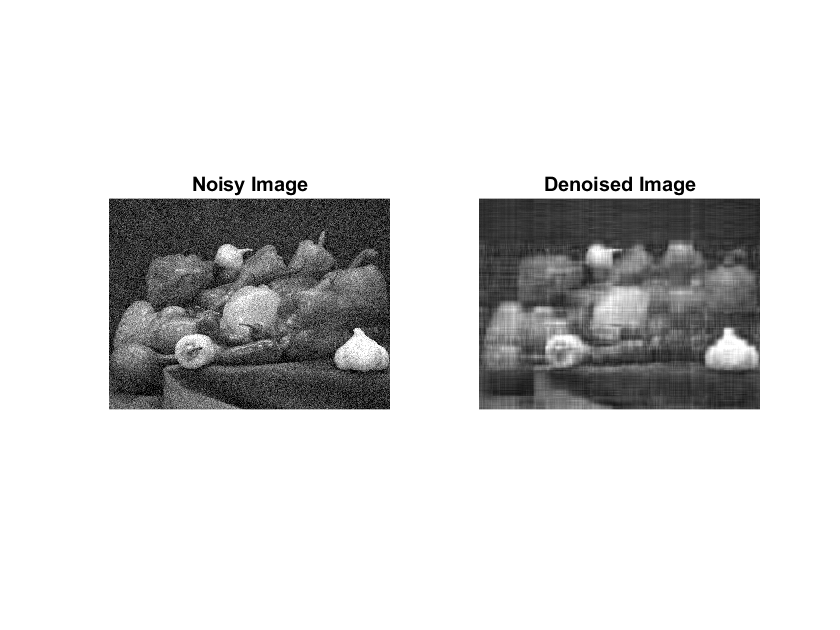

I = imgn1;
% Perform NMF on the noisy image
[W,H] = nnmf(I,15);
% Reconstruct the denoised image
I_denoised = W*H;
% Display the original and denoised images
figure;
subplot(1,2,1);
imshow(I);
title('Noisy Image');
subplot(1,2,2);
imshow(I_denoised);
title('Denoised Image');